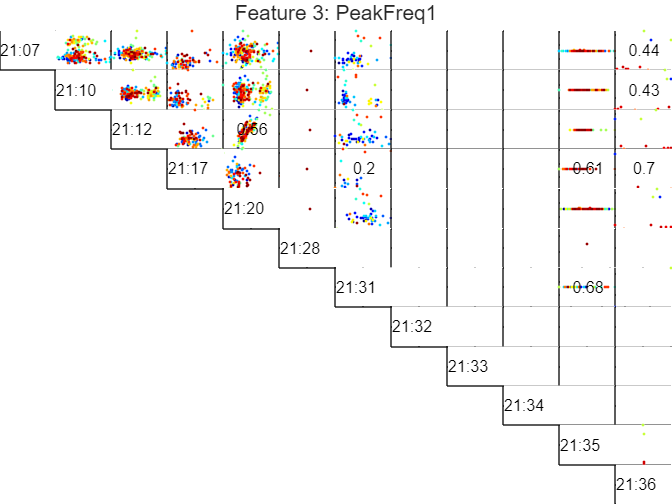

Features = DFD_FeatureTable_FreqDomain;
FeatureNames = featureNames_Freq;
SignalNames = signalNames_Freq;
lowerR2 = 0.2;
upperR2 = 0.8;  
selectedFeature = 3; % Peak Frequency
saveFigures = true;
R2 = fnPlotSignalVsSignal(Features, lowerR2, upperR2, selectedFeature, FeatureNames, SignalNames, sensorNames); 

disp(num2str(R2, '%.2f  '));

0.00   0.00   0.00   0.11   0.00    NaN   0.14    NaN    NaN    NaN   0.81   0.44
0.00   0.00   0.01   0.01   0.01    NaN   0.05    NaN    NaN    NaN   0.85   0.43
0.00   0.00   0.00   0.00   0.56    NaN   0.01    NaN    NaN    NaN   0.82   0.04
0.00   0.00   0.00   0.00   0.00    NaN   0.20    NaN    NaN    NaN   0.61   0.70
0.00   0.00   0.00   0.00   0.00    NaN   0.00    NaN    NaN    NaN   0.82   0.05
0.00   0.00   0.00   0.00   0.00   0.00    NaN    NaN    NaN    NaN    NaN    NaN
0.00   0.00   0.00   0.00   0.00   0.00   0.00    NaN    NaN    NaN   0.68   1.00
0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00    NaN    NaN    NaN    NaN
0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00    NaN    NaN    NaN
0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00    NaN    NaN
0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00  -0.00
0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   0.00   1.00


selectedSignal = 3; % row number
selectedFeature = selectedFeature + 13;
[selectedSignalArray, selectedSignalData, numOfSelectedSignals] = fnSelectSignals(...
    selectedSignal, selectedFeature, featureArray, R2, upperR2, lowerR2, r2ReducedThreshold, true);

     3     5

     3     5



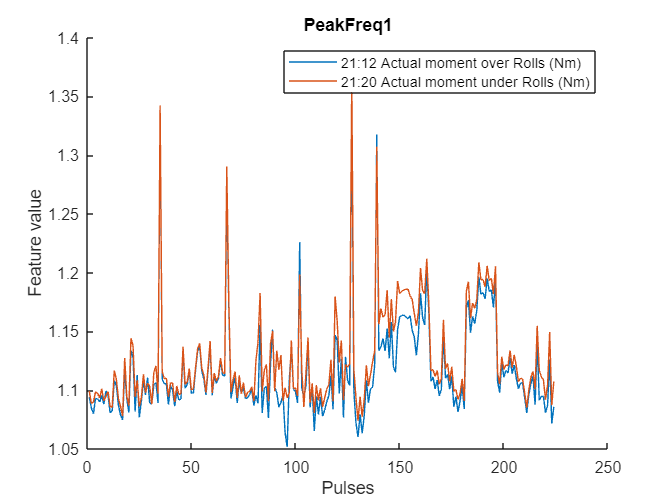

figure(); hold on;
title(FeatureNames(selectedFeature));
xlabel("Pulses");
ylabel("Feature value");
secondaryAxisArrayIndex = [];
for i = 1:numOfSelectedSignals
%     if ismember(i, secondaryAxisArrayIndex)
%         yyaxis right;
%     else
%         yyaxis left;
%     end
    plot(selectedSignalData{i});
    leg{i} = char(sensorNames(selectedSignalArray(i)));
end
legend(leg);

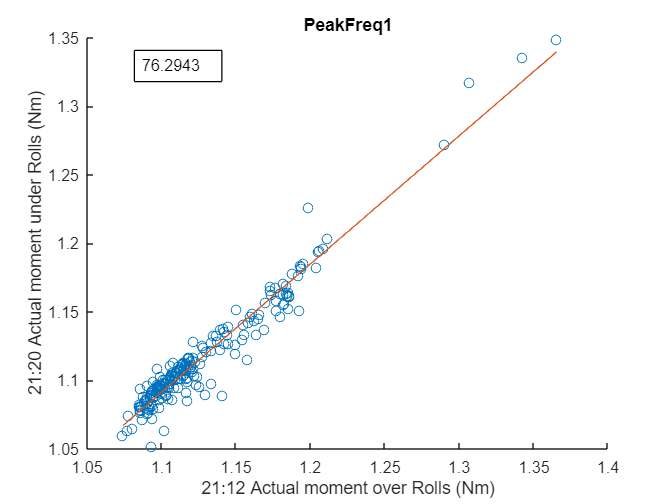

selectedSignalIdx = find(selectedSignalArray == selectedSignal);
for index = 1 : numOfSelectedSignals
    if selectedSignalArray(index) ~= selectedSignal
        fnPlotModel(selectedSignalData{selectedSignalIdx}, ...
            selectedSignalData{index}, ...
            FeatureNames_Combined(selectedFeature), ...
            sensorNames(selectedSignalArray(index)), ...
            sensorNames(selectedSignal));
    end
end

if numOfSelectedSignals > 2
    for index1 = 1 : numOfSelectedSignals
        for index2 = index1+1 : numOfSelectedSignals
            if selectedSignalArray(index1) ~= selectedSignal && selectedSignalArray(index2) ~= selectedSignal 
                fprintf("%i %i %i", selectedSignalIdx, index1, index2);
                Y_est = fnPlotModel3D( ...
                    selectedSignalData{selectedSignalIdx}, ...
                    selectedSignalData{index1}, ...
                    selectedSignalData{index2}, ...
                    FeatureNames_Combined(selectedFeature), ...
                    sensorNames(selectedSignalArray(selectedSignalIdx)), ...
                    sensorNames(selectedSignalArray(index1)), ...
                    sensorNames(selectedSignalArray(index2)));
            end
        end
    end
end